# A full worked example of a satellite pass simulation

Here we will go through a full worked example of using Qrackling to simulate quantum key distribution between a satellite and a ground station in a downlink configuration. The details of this guide follow the contents of the two functions that define the SPOQC satellite and the HOGS ground station, for those interested in reading those instead they can be found as follows:

## The transmitter

First we will define the transmitter, in this case it will be a satellite conforming to the specifications of the UK Quantum Communications Hub qkd satellite project SPOQC (Satellite Platform for Optical Quantum Communications). To do so we need to define the:

- Source

- Telescope

- (Optionally) A Downlink Beacon and Uplink Camera

- Orbit Details

### Source

In Qrackling sources have the following interface comprised mostly of optional fields allowing for a broad range of conditions to be considered:

The options chosen when configuring the source are checked later when attempting to use a QKD protocol as each protocol has a set of requirements that must be met for it to be compatible with a source, this will be discussed later when we are ready to run a simulation. The details of the source we are interested in can be found [here](https://doi.org/10.1117/12.2645103) ([arXiv](https://arxiv.org/abs/2211.10814)) in the *"Design and test of optical payload for polarization encoded QKD for Nanosatellites" *from the SPOQC team.

% source wavelength (nm)
QKD_wavelength = 785;
% create source
source = components.Source( ...
    QKD_wavelength,       ...
    'MPN_Signal',         0.8,   ...
    'MPN_Decoy',          0.3,   ...
    'Probability_Signal', 0.5,   ...
    'Probability_Decoy',  0.25,  ...
    'Repetition_Rate',    1e8,   ...
    'g2',                 0.01,  ...
    'Efficiency',         1,     ...
    'State_Prep_Error',   0.0025 ...
);

### Satellite Main Telescope

Next we will define the satellites telescope, the interface to the telescope class is defined below, much like the source class most of the fields in this constructor are optional:

The paramters specified can be found [here](https://www.mdpi.com/2410-387X/4/1/7) in *"Quarc: Quantum research cubesat—a constellation for quantum communication", *again from the SPOQC team.

OGS_telescope = components.Telescope( ...
    0.08,                      ... % telescope diameter in m
    'Wavelength',         QKD_wavelength, ...
    'Optical_Efficiency', 1,   ... % telescope optical efficiency (unitless)
    'Pointing_Jitter',    1e-6 ... % telescope rms pointing error in rads
);

### (Optional) Downlink Beacon and Uplink Camera

The addition of a beacon camera is not necessary for simulating the QKD channel between the ground station and the satellite but does allow for the simualtion of beacon performance providing some insight into whether or not tracking between the two can be acheived. To do so we first create a telescope to act as the beacon lasers optics such that we can send a beacon signal to the ground station and then define a camera is used to track the beacon signal coming from the ground station. The beacon laser details can be found in the linked *QUARC* paper above. It should also be noted here that the inclusion (exclusion) of a beacon simulation does not effect the results of the QKD simulation as the satellites main telescope has its pointing performance specified by the *"Pointing_Jitter"* field of its constructor.

downlink_beacon_wavelength = 685;
downlink_beacon_telescope = components.Telescope( ...
    0.01,                                             ...
    'FOV',                deg2rad(0.4),               ...
    'Wavelength',         downlink_beacon_wavelength, ...
    'Optical_Efficiency', 1,                          ...
    'Pointing_Jitter',    1e-3);

downlink_beacon_power = 2; % in Watts

% then include this telescope in the beacon object. 
% This uses a flat-top beacon profile but a gaussian 
% beacon is also available
downlink_beacon = beacon.Flat_Top_Beacon( ...
    downlink_beacon_telescope, ...
    downlink_beacon_power, ...
    downlink_beacon_wavelength);

#### Uplink Beacon Camera

Qrackling includes a *Camera* class constructed with the following interface, we can use this to define a camera on the satellite to image and track the uplink beacon from the ground station:

Now we can define the accompanying uplink telescope and camera.

% wavelength of uplink beacon channel
uplink_beacon_wavelength = 850;

% create a telescope for the camera (in reality this is a focussing lens)
uplink_beacon_camera_telescope = components.Telescope( ...
    0.08,                                           ...
    'Wavelength',         uplink_beacon_wavelength, ...
    'Optical_Efficiency', 1,                        ...
    'Focal_Length',       0.86,                     ...
    'Pointing_Jitter',    1e-3); % pointing precision (this is likely tied to the
                                 % satellite's body pointing precision)


There are many properties to every camera, which determine SNR and efficiency. To avoid specifying these, we will load an implementation of the [CMV4000](https://ams.com/documents/20143/36005/CMV4000_DS000728_5-00.pdf).

uplink_beacon_camera = CVM4000( ...
    uplink_beacon_camera_telescope, ...
    0.001,                          ... % camera exposure time in s
    10);                                % spectral filter width in nm

### Orbit Details

For creating orbits we make use of the [MATLAB satellite communications toolbox](https://uk.mathworks.com/products/satellite-communications.html), this provides some convenient functionality to generate orbital path data from either [Kepler elements](https://en.wikipedia.org/wiki/Orbital_elements) or from [two-line element sets (TLE)](https://en.wikipedia.org/wiki/Two-line_element_set). For this example we define the Kepler elements for an orbit resulting in an overpass over the HOGS site at Heriot-Watt University.

altitude = 600e3; % km
semimajor_axis = altitude + earthRadius();
% eccentricity is 0 for a circular orbit. this is a measure of how
% elliptical an orbit is
eccentricity = 0;
% for a sun-synchronous circular orbit, inclination is a function of
% altitude only. we provide a function which can compute the requires
% inclination
inclination = SunSynchronousPolarOrbit(altitude/1000);
% these parameters control the orbit's orientation wrt the earth's surface
right_ascension_of_ascending_node = -1.5;
argument_of_periapsis = 0;
% true anomaly describes where the satellite lies in its orbit
true_anomaly = 0;

Typicall most LEO orbits have more than 1 viable pass per day, the following three pass times are all valid:

- 2022-12-25, 6:56:0

- 2022-12-25, 16:19:0

- 2022-12-25, 17:54:0

pass_time = datetime(2022,12,25,6,56,0);

Simulation duration, an hour is plenty to cover a full pass inlcuding acquisition

duration = minutes(60);
% sample time. 1s samples is the default. longer samples will give better
% performance
sample_time = seconds(1);
% we need to pass a start and stop time
start_time = pass_time - duration / 2;
stop_time = pass_time + duration / 2;

### Constructing the Satellite

We can now combine the above sections into the satellite constructor like so:

% 1.4 construct satellite
spoqc = nodes.Satellite( ...
    OGS_telescope,                   ...
    'Name',                          'SPOQC',                           ...
    'Source',                        source,                            ...
    'Beacon',                        downlink_beacon,                   ...
    'Camera',                        uplink_beacon_camera,              ...
    'SemiMajorAxis',                 semimajor_axis,                    ...
    'eccentricity',                  eccentricity,                      ...
    'inclination',                   inclination,                       ...
    'rightAscensionOfAscendingNode', right_ascension_of_ascending_node, ...
    'argumentOfPeriapsis',           argument_of_periapsis,             ...
    'trueAnomaly',                   true_anomaly);                          % simulation interval in s

## The receiver (Ground Station)

For the ground station we will follow the current specifications of HOGS for this we will need to define the following elements:

- Quantum Receiver 

- (Optionally) A Downlink Camera and Uplink Beacon

- A location for the Ground Station

### Quantum Receiver

The quantum receiver comprises a telescope and a detector, the detector also requires a spectral filter.

#### Telescope

The ground station telescope is likely to be much larger than the satellite's, but is constructed in the same way

% construct a telescope
OGS_telescope = components.Telescope( ...
    0.7,                           ... % telescope diameter (m)
    'Pointing_Jitter',       1e-6, ... % rms pointing error (rads)(after beacon)
    'Optical_Efficiency',    1,    ... % optical efficiency (1 is the default)
    'Focal_Length',          0.4,  ... % telescope focal length (m)
    'Eyepiece_Focal_Length', 0.076 ... % telescope eye piece focal length (m)
);

#### Spectral Filter

We want to restrict the wavelengths that are visible to our detector, for this we can construct a spectral filter. This will be an ideal band pass filter so we can restrict our simulation to only the quantum wavelength transmitted from the satellite.

spectral_filter = components.IdealBPFilter(source.Wavelength, 5);

#### Detector

For further details about detectors the detector preset example can be viewed, this contains details of how to define and save details of a specific detector you are interested in using within this model. To make this easier and to allow people to start comparing results across different devices we have provide some predefined presets these can be selected by changing the argument (a string) of *components.loadPreset *to one of the following options:

- Excelitas

- Hamamatsu

- LaserComponents

- MicroPhotonDevices

- PerkinElmer

- ID_Qube_NIR

- QuantumOpus1550_RoomTemperatureAmplifier

- QuantumOpus1550_CryogenicAmplifier

Each of these detector have different performance characteristics, operational wavlengths, jitters, etc, etc and will result in different received key rates and QBERS. Here we will use the *"Excelitas".*

% construct detector
detector = components.Detector( ...
    QKD_wavelength,         ...
    source.Repetition_Rate, ...
    2e-9,                   ... % time gate width in s
    spectral_filter,        ...
    "Preset", components.loadPreset("Excelitas") );

### (Optional) Downlink Camera and Uplink Beacon

Much like with the satellite we can also define a beacon and camera for the ground station, this can the be used to simulate the tracking performance of the ground station with respect to the satellite.

#### Downlink Beacon Camera

First we define the beacon cameras optics, a telescope (similar to before):

downlink_beacon_camera_telescope = components.Telescope(...
     0.4,                                             ... % telescope diameter (m)
    'Wavelength',         downlink_beacon.Wavelength, ...
    'Optical_Efficiency', 1,                          ... % telescope efficiency (1 is default)
    'Focal_Length',       2.72,                       ... % telescope focal length (m)
    'Pointing_Jitter',    1e-3);                          % rms pointing error (rad)

And just like with the beacon camera on the satellite we have collected some details about the [AC4040 from DIffraction LImited](https://diffractionlimited.com/product/aluma-ac4040/) used at HOGS for beacon tracking:

downlink_beacon_camera = AC4040( ...
    downlink_beacon_camera_telescope, ...
    0.01, ... % exposure time (s)
    10);      % filter width in n, )

#### Uplink Beacon Laser

We can specify beam divergence manually (in rads) rather than approximate it construct telescope. Since in this example the telescope is the same as the downlink beacon camera, we can modify the existing telescope

uplink_beacon_telescope = SetWavelength(downlink_beacon_camera_telescope, uplink_beacon_wavelength);

% construct beacon
uplink_beacon = beacon.Gaussian_Beacon( ...
    uplink_beacon_telescope,     ...
    40e-3,                       ... % power of uplink beacon (W)
    uplink_beacon_wavelength,    ...
    "Power_Efficiency",       1, ... % power efficiency of the uplink beacon optics
    "Pointing_Jitter",        1e-6); % rms pointing error of uplink beacon


### Constructing the Ground Station

Combining the above into *Ground_Station* constructor will then give us our object for HOGS

hogs = nodes.Ground_Station( ...
    OGS_telescope, ...
    'Detector',    detector,                   ...
    'Camera',      downlink_beacon_camera,     ...
    'Beacon',      uplink_beacon,              ...
    'LLA',         [55.909723, -3.319995, 10], ...
    'name',        'Heriot Watt');

## Environmental Conditions

As part of Qrackling we have defined an *"Environment" *class that is used to hold transmission and radiance data about a ground station site. Compared to the rest of the model this can be seen as the most involved part as you will need to combine data from your sources of choice, we provide some convenience functions and an interface to [libRadtran](http://www.libradtran.org/doku.php) but that is outside the scope of this example. The *Environment* class accepts transmission data in either decibel or as an efficiency (0 to 1) and radiance data in units of: $\frac{W}{\textrm{sr}\;m^{2\;} \textrm{nm}}$.

Here we will make use of radiance data collected here at Heriot-Watt University as an example of the background light sources present at night, for this we will first bring in the data:

%sky brightness store for the ground station
loc = which("nodes.Satellite");
[path, ~, ~] = fileparts(loc);
elems = strsplit(path, filesep);
path_root = string(join(elems(1:end-2), filesep)) + filesep;
whichSeparator = @(Path, Sep) Sep{cellfun(@(sep) contains(Path, sep), Sep)};
MakePathNative = @(Path) strjoin(strsplit(Path, whichSeparator(Path, {'/', '\'})), filesep);
brightness_data = load(path_root + MakePathNative("Examples/Data/measured background counts/HWU_Experimental_Sky_Brightness.mat")).data;

Next we will define a range of heading and elevations that we want the data to be used over and interpolate collected data onto the resulting grid. We will use these headings and elevations again later to perform the same operation on the transmission data and then finally when constructing the environment.

sky_brightness = permute(brightness_data.Spectral_Pointance,[3,1,2]);

sky_elevations = linspace(0, 90, 46);
sky_headings = linspace(0, 360, 91);

mapped_night_sky = environment.mapToEnvironment( ...
    brightness_data.Headings, ...
    brightness_data.Elevations, ...
    sky_brightness, ... %780nm is at index 1
    sky_headings, ...
    sky_elevations, ...
    "Wavelength", brightness_data.Wavelengths);

    23     8

     2    23     8



Now we will take some data generated from [MODTRAN](http://modtran.spectral.com/), import it and sort them according to the elevation angle it was calculated for:

loc = which('utilities.readModtranFile');
[path, ~, ~] = fileparts(loc);
elems = strsplit(path, filesep);
path_root = string(join(elems(1:end-1), filesep)) + filesep;
example_path = "Examples/Data/atmospheric transmittance/varying elevation MODTRAN data 2/";
data_path = path_root + MakePathNative(example_path);
paths = dir(data_path);
FilterStrings = @(haystack, needle) haystack(arrayfun(@(h) contains(h, needle), haystack));
csv_files = FilterStrings({paths.name}, ".csv");
disp(csv_files')

    {'Transm_100km_obs_zen_0deg_scan.csv' }
    {'Transm_100km_obs_zen_10deg_scan.csv'}
    {'Transm_100km_obs_zen_20deg_scan.csv'}
    {'Transm_100km_obs_zen_30deg_scan.csv'}
    {'Transm_100km_obs_zen_40deg_scan.csv'}
    {'Transm_100km_obs_zen_50deg_scan.csv'}
    {'Transm_100km_obs_zen_60deg_scan.csv'}
    {'Transm_100km_obs_zen_70deg_scan.csv'}
    {'Transm_100km_obs_zen_80deg_scan.csv'}
    {'Transm_100km_obs_zen_90deg_scan.csv'}



The files in this directory following a naming scheme with the folling structure: { data type, visibility, label, zenith label, zenith angle, _, .extensions }. Since we want to read the data in from these files in order of their zenith angles we will have to split their file names into these elements and then sort the array according to zenith angles.

schema = {'data_type', 'visibility', 'visibility_label', 'zenith_label', 'zenith_angle', 'end'};
file_details = cellfun(@(f) cell2struct(split(f, "_"), schema), csv_files);
elevations = sort(str2double(replace({file_details.zenith_angle}, "deg", "")));
sorted_file_names = string( ...
    arrayfun( ...
        @(n) csv_files(contains(csv_files, "_" + num2str(n) + "deg")), ...
        elevations, ...
        UniformOutput=false)');
disp(sorted_file_names)

    "Transm_100km_obs_zen_0deg_scan.csv"
    "Transm_100km_obs_zen_10deg_scan.csv"
    "Transm_100km_obs_zen_20deg_scan.csv"
    "Transm_100km_obs_zen_30deg_scan.csv"
    "Transm_100km_obs_zen_40deg_scan.csv"
    "Transm_100km_obs_zen_50deg_scan.csv"
    "Transm_100km_obs_zen_60deg_scan.csv"
    "Transm_100km_obs_zen_70deg_scan.csv"
    "Transm_100km_obs_zen_80deg_scan.csv"
    "Transm_100km_obs_zen_90deg_scan.csv"



#### Extracting MODTRAN Data

With the files now in order we can read in the wavelength and transmission data from each and construct a matrix for them. The *utilities.readModtranFile* function pull these columns from a typical MODTRAN file. The *environment.allSkyTransmission* function then allows us to convert the transmission data into a matrix with dimensions 

that we can then plot on polar axes.

wavelengths = [];
transmissions = [];
for f = sorted_file_names'
    [w, t] = utilities.readModtranFile(char(data_path + f));
    wavelengths = [wavelengths, w(~isnan(w))];
    transmissions = [transmissions, t(~isnan(t))];
end
[sky_transmission, headings] = environment.allSkyTransmission(transmissions, wavelengths(:, 1), elevations);

#### Filtering

Since our files contain data for a range of wavelenths we can construct the following lambda functions to find the correct slice of our transmission matrix for a chosen wavelength.

Extrema = @(arr) [min(arr), max(arr)];
InRange = @(value, bounds) all([any(value >= bounds), any(value <= bounds)]);
Iota = @(x) linspace(0, x, x+1);
Take = @(arr, choices) arr(choices);
IndexOfWavelength = @(wvls, choice) Take(Iota(numel(wvls)), wvls == choice) * InRange(wvls, Extrema(wvls));
DataAtWavelength = @(data, wvls, choice) squeeze(data(IndexOfWavelength(wvls, choice), :, :));
% Picking an example wavelength of 600nm we can then plot the result.

tmp_size = [numel(brightness_data.Wavelengths), size(squeeze(sky_transmission(1, :, :)))];
transmission_at_wavelength = zeros(tmp_size);
for i = 1:numel(brightness_data.Wavelengths)
    wvl = brightness_data.Wavelengths(i);
     transmission_at_wavelength(i, :, :) = ...
         DataAtWavelength(sky_transmission, wavelengths(:, 1), wvl);
end

WIth the data for the wavlength we are operating at now extracted we can generate an interpolated matrix to represent the dome of sky visible from the ground station:

mapped_transmission = environment.mapToEnvironment( ...
    headings, ...
    elevations, ...
    transmission_at_wavelength, ...
    sky_headings, ...
    sky_elevations, ...
    "Wavelengths", brightness_data.Wavelengths);

     9    10

     2     9    10



Finally we can combine the heading and elevation angles with the radiance and transmission data to construct the *"Environment"* object that we will use in our simulation.

Env = environment.Environment(sky_headings, sky_elevations, ...
    brightness_data.Wavelengths, mapped_night_sky, mapped_transmission);

## Running Simulations

With all of the setup and configuration we are now ready to begin simulating satellite to ground communications, as such we will first pick a QKD protocol to use:

Protocol = protocol.decoyBB84();

Running QKD simulations and beacon simulations can be done in similar ways, first the simulation function is passed a receiver, second a transmitter, in the case of the QKD simulation we then need a protocol and finally we can add an optional environment argument to each of them to include data about the ground stations environment.

result = nodes.QkdPassSimulation(hogs, spoqc, Protocol, 'Environment',Env,...
    'startTime',                     start_time,                        ... % start of simulation
    'stopTime',                      stop_time,                         ... % end of simulation
    'sampleTime',                    sample_time);
beacon_result_down = beacon.beaconSimulation(hogs, spoqc, Environment=Env);
beacon_result_up = beacon.beaconSimulation(spoqc, hogs, Environment=Env);

### Plotting Results

Each simulation result object has a plotResult method which plots a standard dashboard of results. Otherwise, results can be accessed from these objects as read-only properties

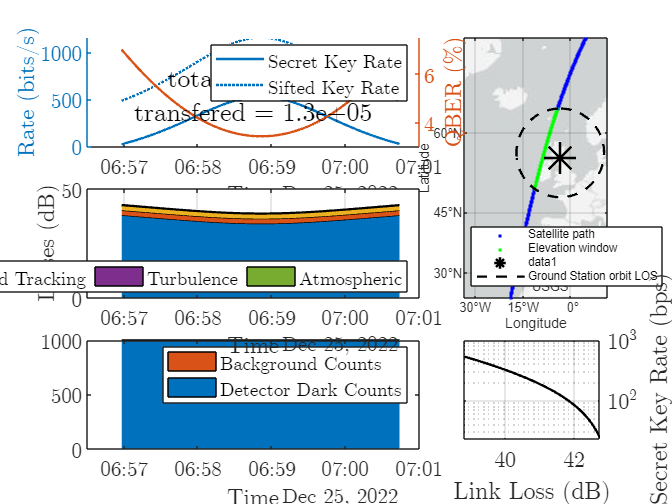

QKD_figure = result.plotResult(hogs, spoqc, "mask", "Elevation");

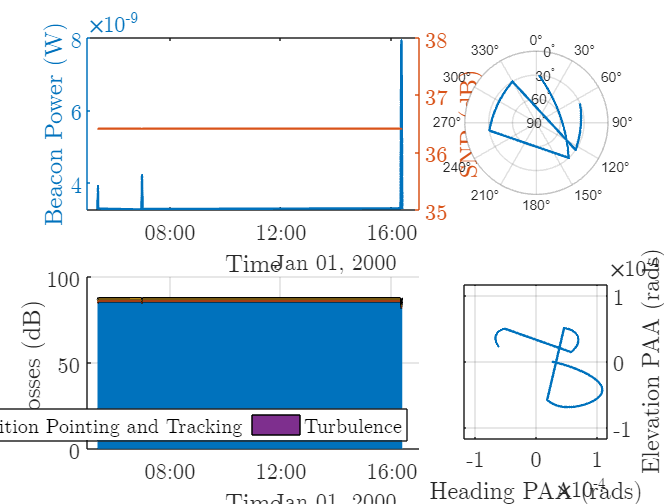

beacon_down_figure = beacon_result_down.plot("mask", "Elevation");

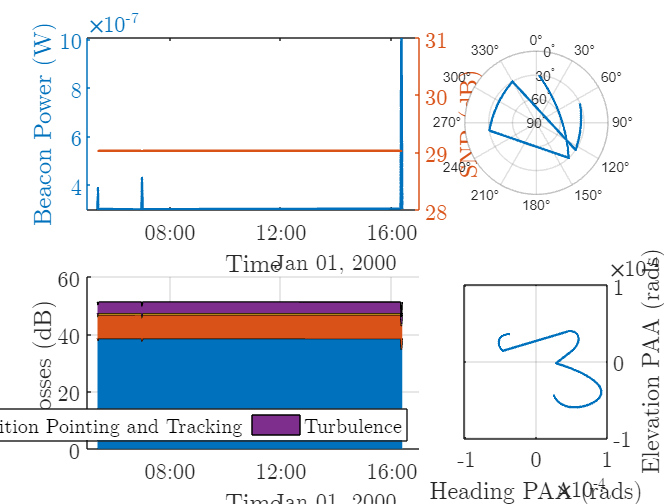

beacon_up_figure = beacon_result_up.plot("mask", "Elevation");